+pto 3 taller

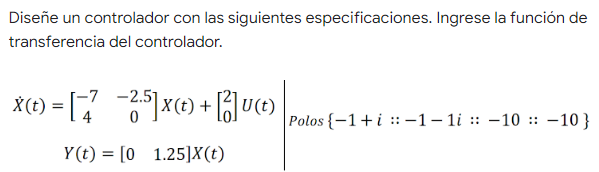

s=tf('s');

A=[-7 -2.5;4 0]
B=[2;0]
C=[0 1.25]

G=ss(A,B,C,0)

G =
 
  A = 
         x1    x2
   x1    -7  -2.5
   x2     4     0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
         x1    x2
   y1     0  1.25
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



G1=tf(G)

G1 =
 
        10
  --------------
  s^2 + 7 s + 10
 
Continuous-time transfer function.



pole(G)

MC=ctrb(A,B);
rank(MC)

ans = 2


P=poly([-1+i -1-1*i -10 -10])

P =      1    22   142   240   200



Gc=ss(A,B,C,0);
FT=tf(Gc)

FT =
 
        10
  --------------
  s^2 + 7 s + 10
 
Continuous-time transfer function.



pole(FT)

ans =     -5
    -2


GT=[1 0 0 0 0;7 1 0 0 0;10 7 10 0 0;0 10 0 10 0;0 0 0 0 10]

GT =      1     0     0     0     0
     7     1     0     0     0
    10     7    10     0     0
     0    10     0    10     0
     0     0     0     0    10


GL=[1 22 142 240 200]';
G1A=GT\GL

G1A =     1.0000
   15.0000
    2.7000
    9.0000
   20.0000


[A1,B1,C1,D1]=tf2ss(GT,G1A)

A1 =   -15.0000   -2.7000   -9.0000  -20.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B1 =      1
     0
     0
     0


C1 =   -15.0000   -2.7000   -9.0000  -20.0000
 -104.0000  -18.9000  -63.0000 -140.0000
 -143.0000  -17.0000  -90.0000 -200.0000
   10.0000         0   10.0000         0
         0         0         0   10.0000


D1 =      1
     7
    10
     0
     0


C=ss(A1,B1,C1,D1)

C =
 
  A = 
         x1    x2    x3    x4
   x1   -15  -2.7    -9   -20
   x2     1     0     0     0
   x3     0     1     0     0
   x4     0     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
          x1     x2     x3     x4
   y1    -15   -2.7     -9    -20
   y2   -104  -18.9    -63   -140
   y3   -143    -17    -90   -200
   y4     10      0     10      0
   y5      0      0      0     10
 
  D = 
       u1
   y1   1
   y2   7
   y3  10
   y4   0
   y5   0
 
Continuous-time state-space model.



C1=tf(C)

C1 =
 
  From input to output...
                      s^4
   1:  ---------------------------------
       s^4 + 15 s^3 + 2.7 s^2 + 9 s + 20
 
                  7 s^4 + s^3
   2:  ---------------------------------
       s^4 + 15 s^3 + 2.7 s^2 + 9 s + 20
 
       10 s^4 + 7 s^3 + 10 s^2 + 2.499e-14 s
   3:  -------------------------------------
         s^4 + 15 s^3 + 2.7 s^2 + 9 s + 20
 
                 10 s^3 + 10 s
   4:  ---------------------------------
       s^4 + 15 s^3 + 2.7 s^2 + 9 s + 20
 
                      10
   5:  ---------------------------------
       s^4 + 15 s^3 + 2.7 s^2 + 9 s + 20
 
Continuous-time transfer function.



stepinfo(G1A)

ans = struct with fields:
         RiseTime: 3.7468
    TransientTime: 4.9655
     SettlingTime: 4.9636
      SettlingMin: 20
      SettlingMax: 20
        Overshoot: 0
       Undershoot: 0
             Peak: 20
         PeakTime: 5


damp(C1)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.93e-01                 1.00e+00       9.93e-01         1.01e+00    
  4.23e-01 + 1.08e+00i    -3.63e-01       1.16e+00        -2.36e+00    
  4.23e-01 - 1.08e+00i    -3.63e-01       1.16e+00        -2.36e+00    
 -1.49e+01                 1.00e+00       1.49e+01         6.73e-02    
